# Test Case - Engine

Light load inertia with no speed reduction at the gear box.

mdl = "Engine_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
Engine_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

% Light load inertia
simIn = setBlockParameter(simIn, mdl+"/Mechanical Load/Load inertia", inertia="10*0.1^2");
simIn = setBlockParameter(simIn, mdl+"/Mechanical Load/Load inertia", inertia_unit="kg*m^2");

% No reduction at gear box
simIn = setBlockParameter(simIn, mdl+"/Mechanical Load/Gear Box", ratio="1");

simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", Time="3");
simIn = setBlockParameter(simIn, mdl+"/Engine torque command", After="150");

simIn = setBlockParameter(simIn, mdl+"/Axle clutch on off", Before="1");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch on off", Time="5");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch on off", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle speed input", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle speed input", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle speed input", After="900");

simIn = setBlockParameter(simIn, mdl+"/Axle torque input", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle torque input", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle torque input", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.loadInertia_speed_rpm", 0);
simIn = setVariable(simIn, "initial.engine_speed_rpm", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "20");

% Run simulation
simOut = sim(simIn);

## Visualize Simulation Result

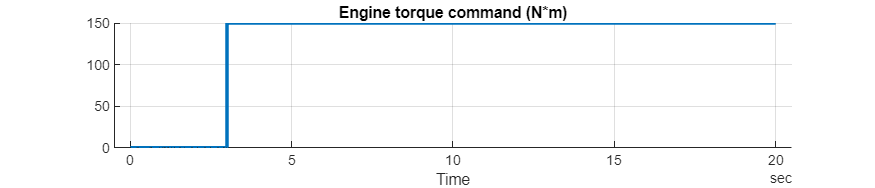

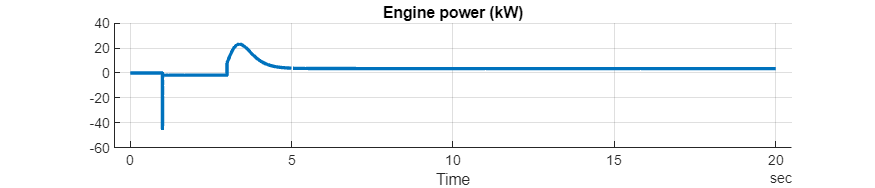

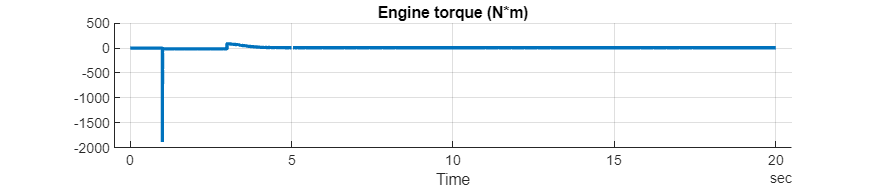

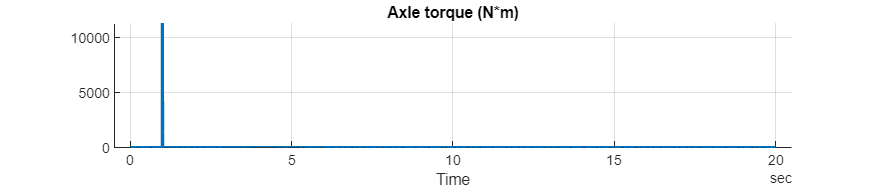

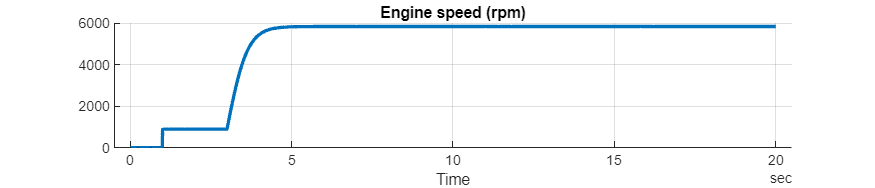

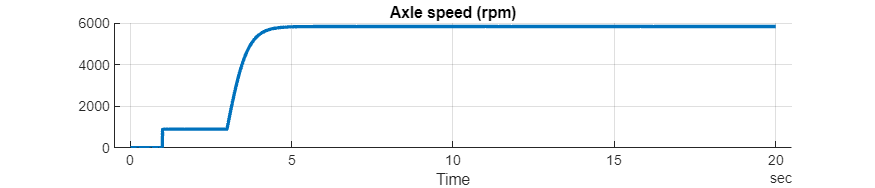

simData = extractTimetable(simOut.logsout);

sigNames = [ ...
  "Engine torque command", ...
  "Engine power", ...
  "Engine torque", ...
  "Axle torque", ...
  "Engine speed", ...
  "Axle speed" ];

for i = 1 : numel(sigNames)
  fig = plotSimulationResultSignal(SimData = simData, SignalName = sigNames(i));
  fig.Position(4) = 150;
end

*Copyright 2021-2022 The Mathworks, Inc.*